# RandomWalk

Repeatedly simulates the outcome of a random walk,  a sequence of random steps, each step with mean 1 (units unspecified) and standard deviation $1/\sqrt{12}$ of the step size.

Author: D. Carlsmith

clear;delete(findall(0,'Type','figure'))%

Set parameters for the simulation. Feel free to change these.

mu = 1;% mean step size
sigma = 1/12^(1/2);% standard deviation of step size
nwalks = 5000; % number of walks to take
nsteps = 10;% total number of steps per walk
normal = 1;% flag 1 for normal distribution, other value for uniform

Loop over walks and generate a vector of random steps for each walk using the functions [normrnd](https://www.mathworks.com/help/stats/normrnd.html), [rand](https://www.mathworks.com/help/matlab/ref/rand.html), and [cumsum](https://www.mathworks.com/help/matlab/ref/cumsum.html).

for ii=1:nwalks
    if normal==1
        xs(ii,:)=normrnd(mu,sigma,nsteps,1);% nsteps of normally distributed steps
    else
        xs(ii,:)=mu+rand(nsteps,1)-.5;% nsteps of uniformly distributed steps
    end
    xtot(ii,:)=cumsum(xs(ii,:));% cumulative sums of steps
end

Histogram the outcomes of the walks for various number of steps.

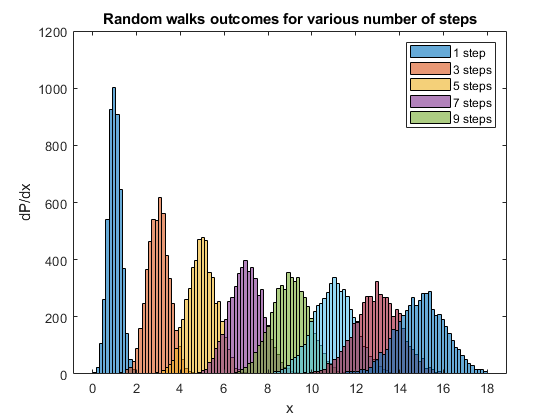

figure
edges = [0:120]*nsteps/100;% histogram bin edges
for istep=1:2:nsteps;% make histograms after each two steps
    for iwalk=1:nwalks;% make list of results of all walks
        x(iwalk)= xtot(iwalk,istep);
    end
    histogram(x,edges);% histogram the position after each two steps
    title('Random walks outcomes for various number of steps');
    xlabel('x');ylabel('dP/dx')
    hold on
end
legend('1 step','3 steps','5 steps','7 steps','9 steps')

Plot some walks as functions of time.

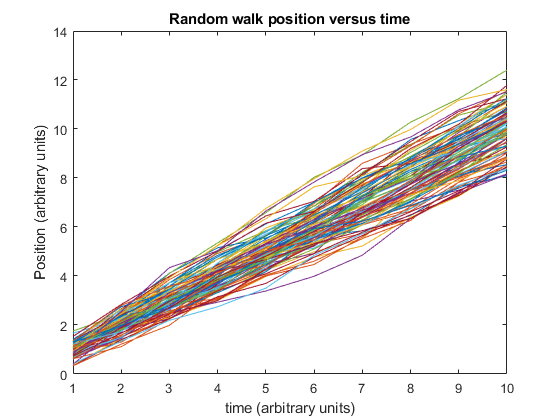

figure
for iwalk=1:nwalks/100:nwalks
    xwalk= xtot(iwalk,:);
    plot(xwalk);hold on
end
title('Random walk position versus time');
xlabel('time (arbitrary units)');ylabel('Position (arbitrary units)')
hold off

% done!